km = 0.3678;
ke = 0.3678;
J = 0.0026;
R = 4.7509;
T = R*J/(ke*km)

T = 0.0913

K = ke^(-1)

K = 2.7189

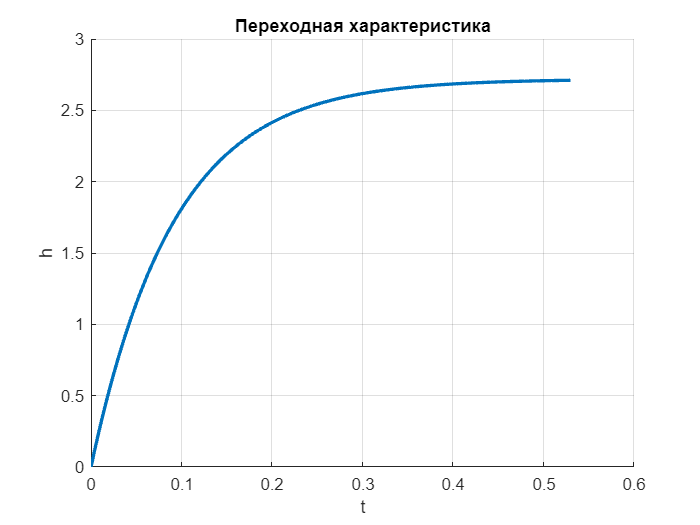


num = K;
den = [T 1];
sys = tf(num, den);

[h, t1] = step(sys);
[w, t2] = impulse(sys);

figure;
hold on;
plot(t1, h, 'LineWidth', 2);
title('Переходная характеристика');
xlabel('t');
ylabel('h');
grid on;
hold off;

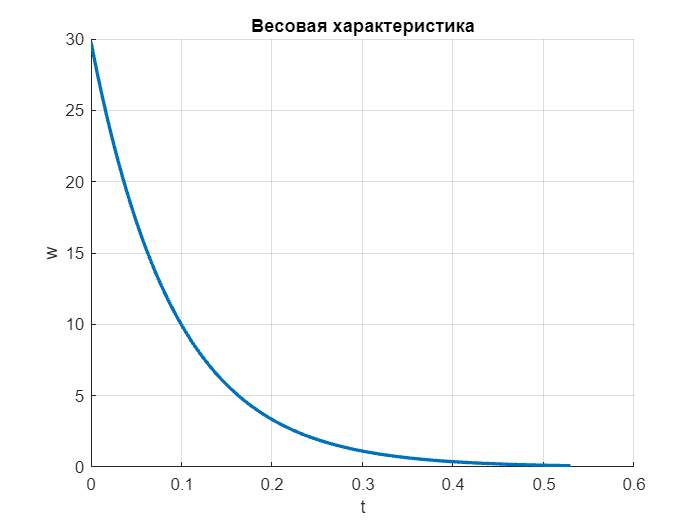


figure;
hold on;
plot(t2, w, 'LineWidth', 2);
title('Весовая характеристика');
xlabel('t');
ylabel('w');
grid on;
hold off;

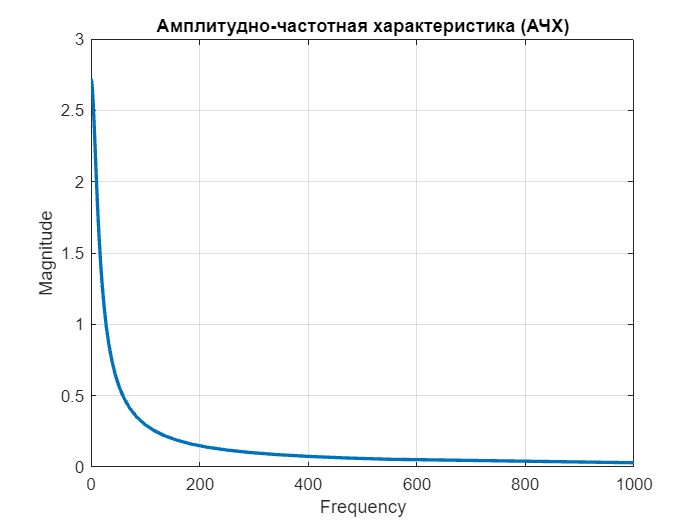


[mag, phase, omega] = bode(sys);
mag = squeeze(mag);
phase = squeeze(phase);

figure;
plot(omega, mag, 'LineWidth', 2);
title('Амплитудно-частотная характеристика (АЧХ)');
xlabel('Частота');
ylabel('Амплитуда');
grid on;

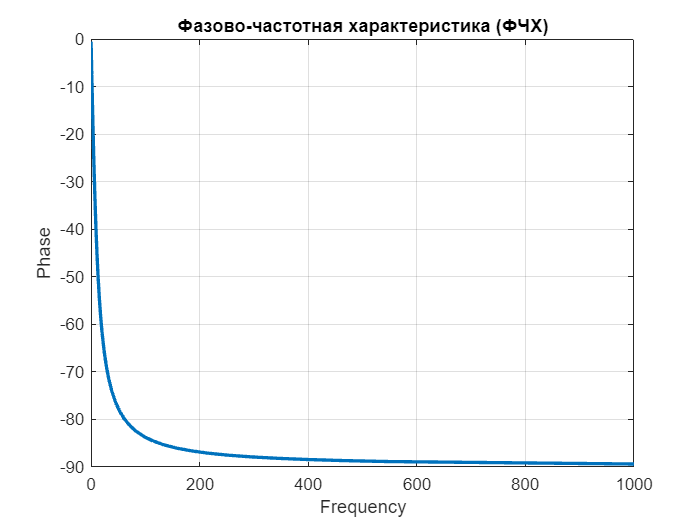


figure;
plot(omega, phase, 'LineWidth', 2);
title('Фазово-частотная характеристика (ФЧХ)');
xlabel('Частота');
ylabel('Фаза');
grid on;

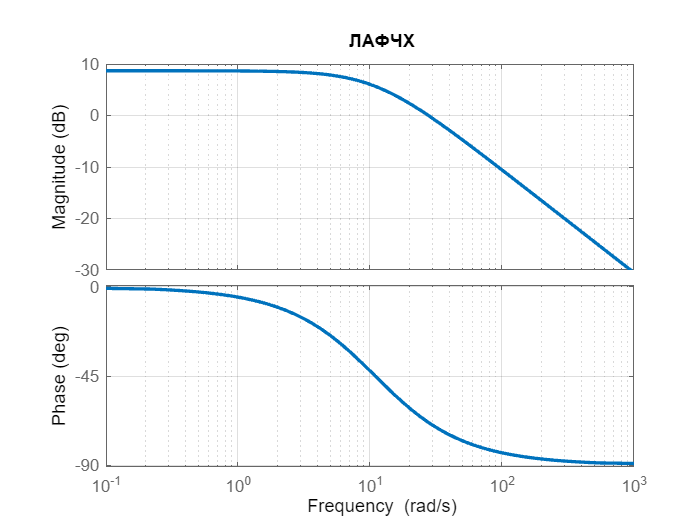


figure;
bode(sys);
grid on;
l = findall(gcf, 'Type', 'line');
set(l, 'LineWidth', 2);           
title('ЛАФЧХ');

km = 0.3460;
ke = 0.3460;
J = 0.0019;
R = 4.6056;
L = 1.1790;
T = sqrt(L*J/(km*ke))

T = 0.1368

xi = R/2*sqrt(J/(L*km*ke))

xi = 0.2672

K = ke^(-1)

K = 2.8902

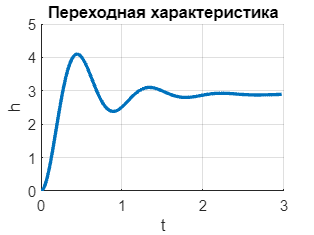


num = K;
den = [T^2 2*xi*T 1];
sys = tf(num, den);

[w, t2] = impulse(sys);
[h, t1] = step(sys);

figure;
hold on;
plot(t1, h, 'LineWidth', 2);
title('Переходная характеристика');
xlabel('t');
ylabel('h');
grid on;
hold off;

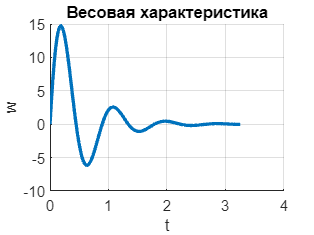


figure;
hold on;
plot(t2, w, 'LineWidth', 2);
title('Весовая характеристика');
xlabel('t');
ylabel('w');
grid on;
hold off;

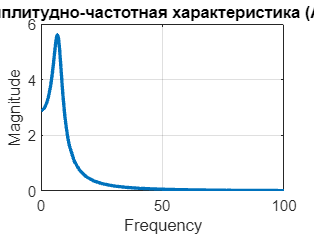


[mag, phase, omega] = bode(sys);
mag = squeeze(mag);
phase = squeeze(phase);

figure;
plot(omega, mag, 'LineWidth', 2);
title('Амплитудно-частотная характеристика (АЧХ)');
xlabel('Частота');
ylabel('Амплитуда');
grid on;

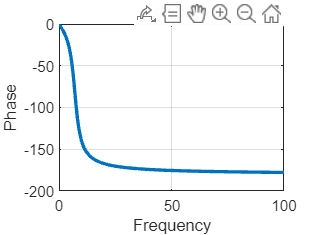


figure;
plot(omega, phase, 'LineWidth', 2);
title('ФЧХ');
xlabel('Частота');
ylabel('Фаза');
grid on;

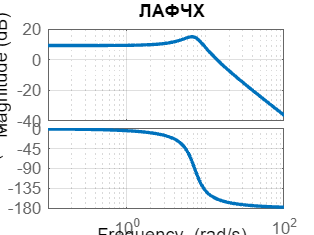


figure;
bode(sys);
grid on;
l = findall(gcf, 'Type', 'line');
set(l, 'LineWidth', 2);           
title('ЛАФЧХ');

C = 263 * 10^(-6);
K = 1/C

K = 3.8023e+03

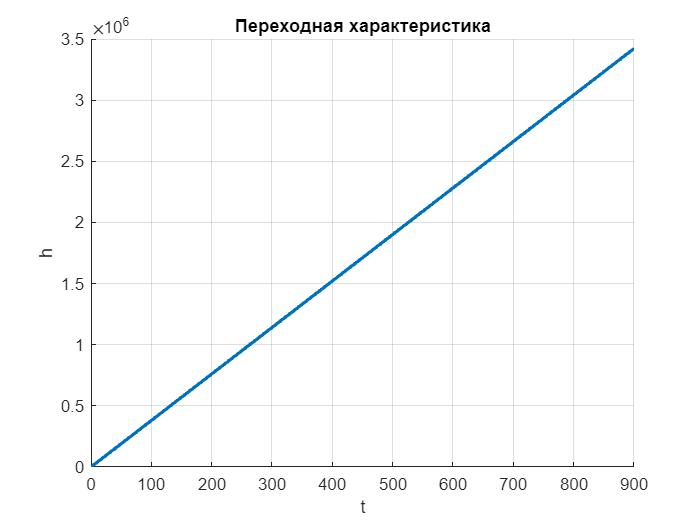


num = K;
den = [1 0];
sys = tf(num, den);

[w, t2] = impulse(sys);
[h, t1] = step(sys);

figure;
hold on;
plot(t1, h, 'LineWidth', 2);
title('Переходная характеристика');
xlabel('t');
ylabel('h');
grid on;
hold off;

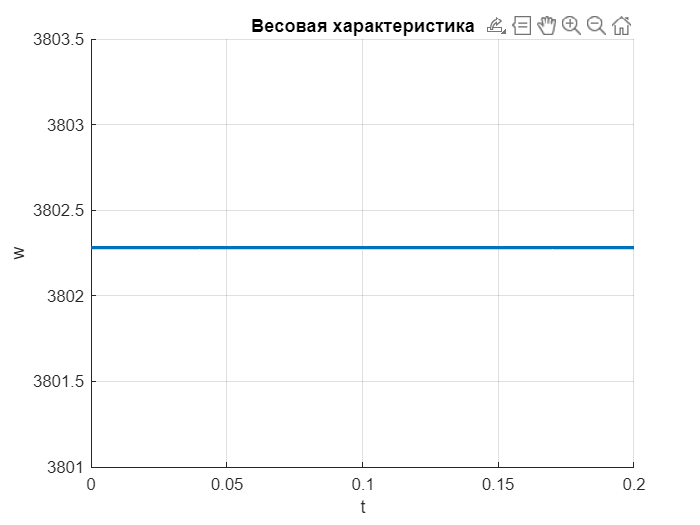


figure;
hold on;
plot(t2, w, 'LineWidth', 2);
title('Весовая характеристика');
xlabel('t');
ylabel('w');
grid on;
hold off;

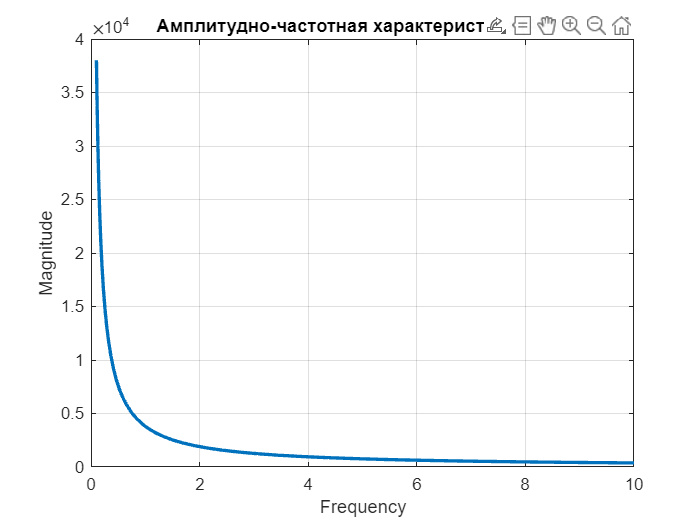


[mag, phase, omega] = bode(sys);
mag = squeeze(mag);
phase = squeeze(phase);

figure;
plot(omega, mag, 'LineWidth', 2);
title('Амплитудно-частотная характеристика (АЧХ)');
xlabel('Частота');
ylabel('Амплитуда');
grid on;

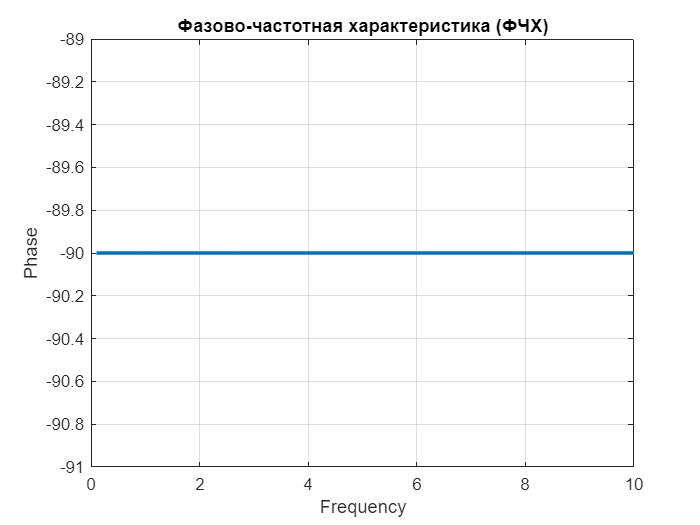


figure;
plot(omega, phase, 'LineWidth', 2);
title('Фазово-частотная характеристика (ФЧХ)');
xlabel('Частота');
ylabel('Фаза');
grid on;

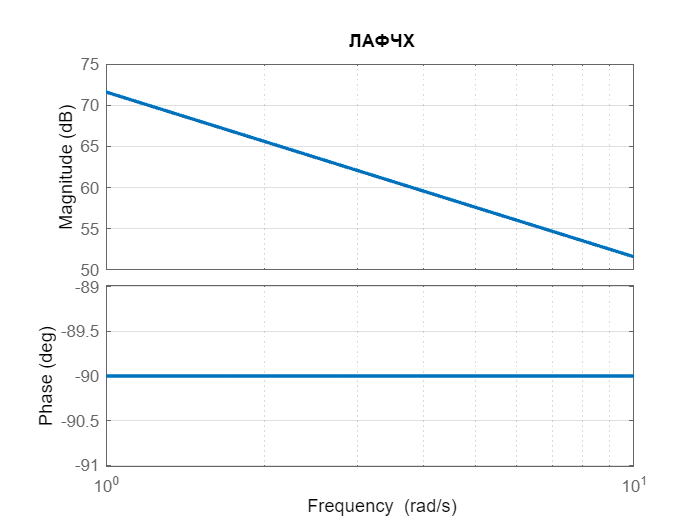


figure;
bode(sys);
grid on;
l = findall(gcf, 'Type', 'line');
set(l, 'LineWidth', 2);           
title('ЛАФЧХ');

m = 35;
k = 122;
K = 1/k

K = 0.0082

T = sqrt(m/k)

T = 0.5356

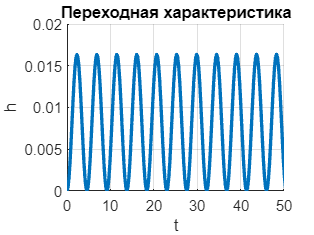


num = K;
den = [T 0 1];
sys = tf(num, den);

[w, t2] = impulse(sys);
[h, t1] = step(sys);

figure;
hold on;
plot(t1, h, 'LineWidth', 2);
title('Переходная характеристика');
xlabel('t');
ylabel('h');
xlim([0, 50]);
grid on;
hold off;

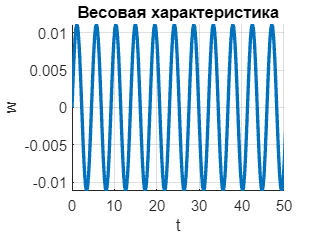


figure;
hold on;
plot(t2, w, 'LineWidth', 2);
title('Весовая характеристика');
xlabel('t');
ylabel('w');
xlim([0, 50]);
grid on;
hold off;

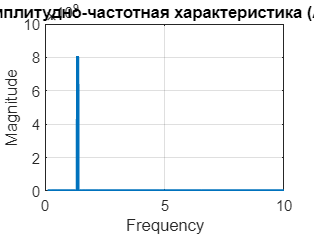


[mag, phase, omega] = bode(sys);
mag = squeeze(mag);
phase = squeeze(phase);

figure;
plot(omega, mag, 'LineWidth', 2);
title('Амплитудно-частотная характеристика (АЧХ)');
xlabel('Частота');
ylabel('Амплитуда');
grid on;

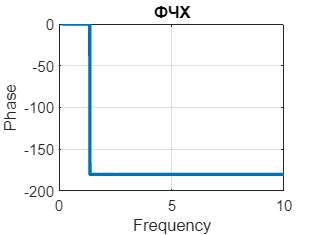


figure;
plot(omega, phase, 'LineWidth', 2);
title('ФЧХ');
xlabel('Частота');
ylabel('Фаза');
grid on;

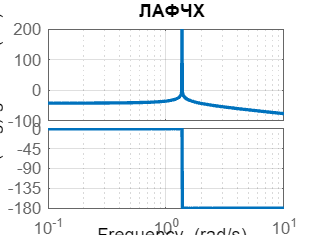


figure;
bode(sys);
grid on;
l = findall(gcf, 'Type', 'line');
set(l, 'LineWidth', 2);           
title('ЛАФЧХ');

R1 = 666;
R2 = 13310;
C = 263*10^(-6);
K = R2/R1

K = 19.9850

T = R2*C

T = 3.5005

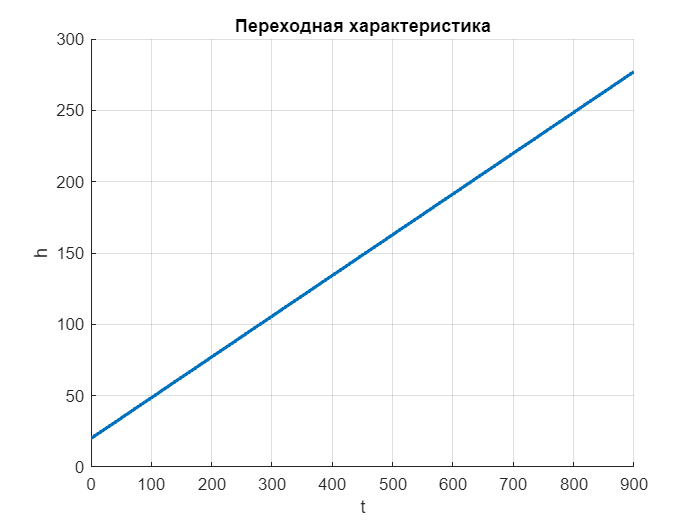


num = [K*T 1];
den = [T 0];
sys = tf(num, den);

[w, t2] = impulse(sys);
[h, t1] = step(sys);

figure;
hold on;
plot(t1, h, 'LineWidth', 2);
title('Переходная характеристика');
xlabel('t');
ylabel('h');
grid on;
hold off;

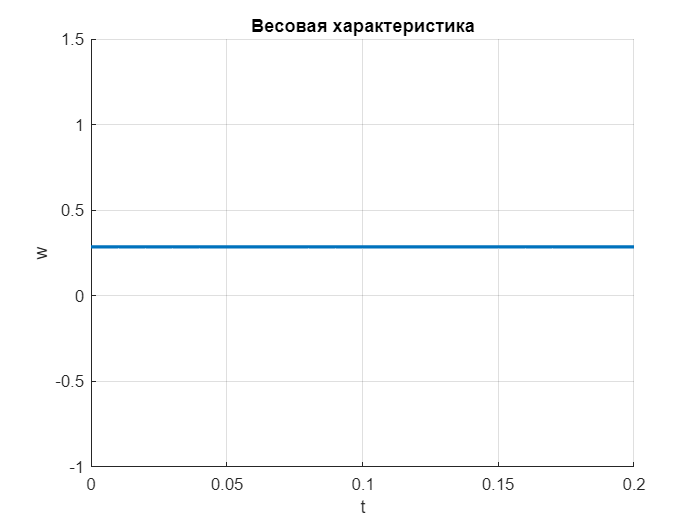


figure;
hold on;
plot(t2, w, 'LineWidth', 2);
title('Весовая характеристика');
xlabel('t');
ylabel('w');
grid on;
hold off;

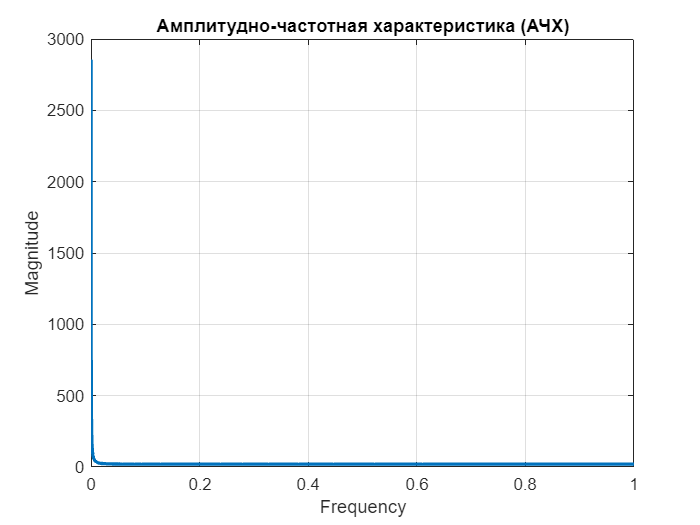


[mag, phase, omega] = bode(sys);
mag = squeeze(mag);
phase = squeeze(phase);

figure;
plot(omega, mag, 'LineWidth', 2);
title('Амплитудно-частотная характеристика (АЧХ)');
xlabel('Частота');
ylabel('Амплитуда');
grid on;

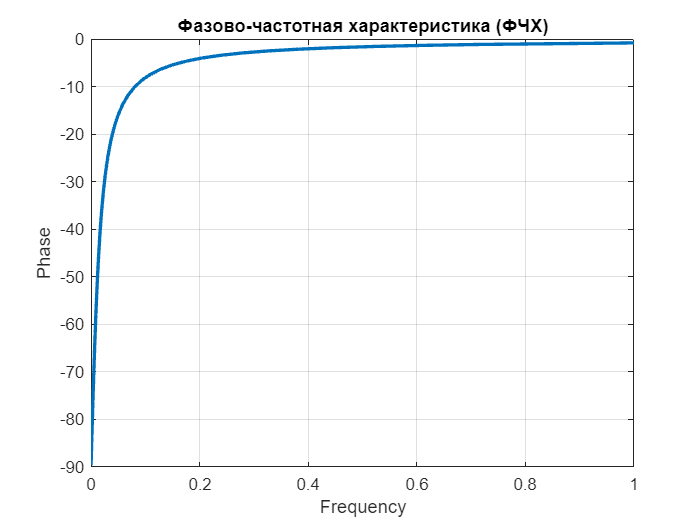


figure;
plot(omega, phase, 'LineWidth', 2);
title('Фазово-частотная характеристика (ФЧХ)');
xlabel('Частота');
ylabel('Фаза');
grid on;

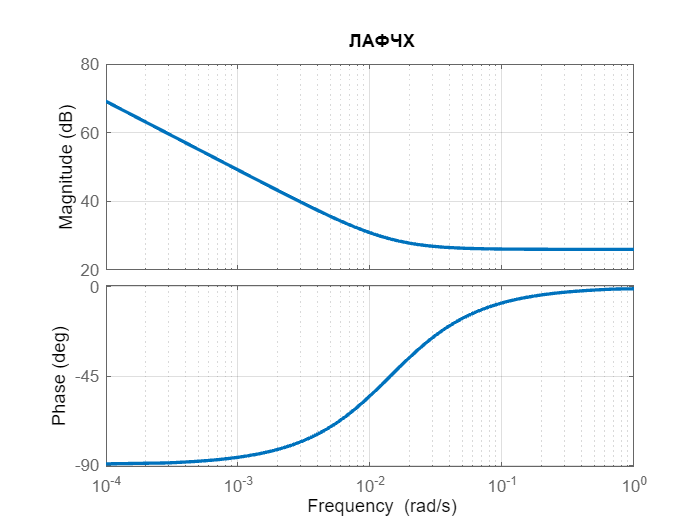


figure;
bode(sys);
grid on;
l = findall(gcf, 'Type', 'line');
set(l, 'LineWidth', 2);           
title('ЛАФЧХ');

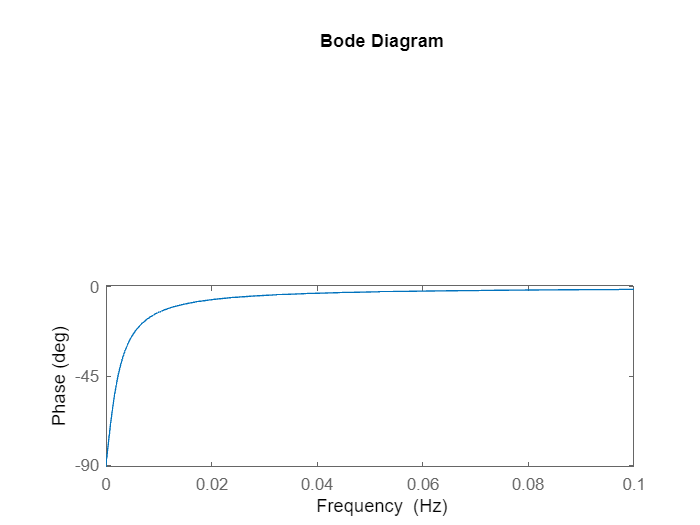


bp = bodeplot(sys);
setoptions(bp, 'FreqUnits', 'Hz', 'FreqScale', 'linear');